 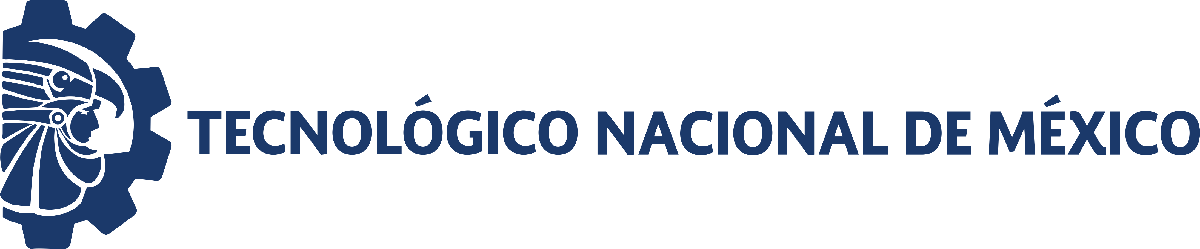                                 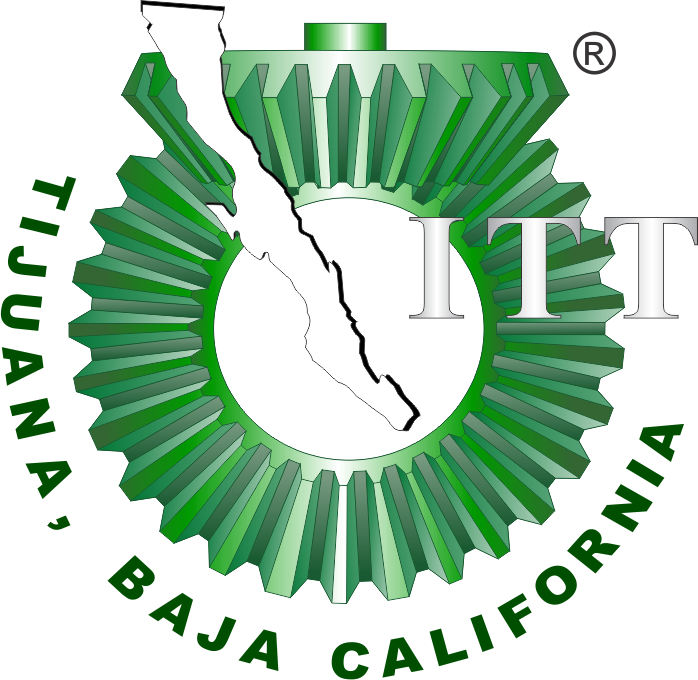

# Final Project

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## General Information

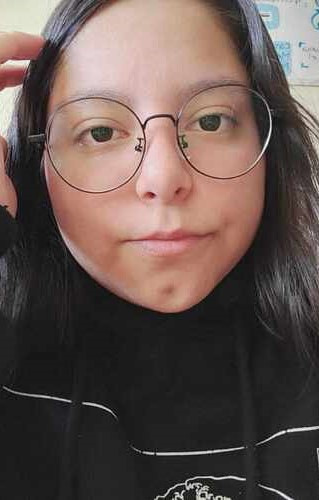

Student name: **Diana Ivana Escalante Esquivel**

Control number: **21212151**

Institutional email: **L21212151@tectijuana.edu.mx**

Subject: **Gemelos Digitales**

Teacher: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objective

Integrate specific skills related to the modeling, analysis, and control of biological systems to illustrate and predict their dynamics over time.

## System description

The system represents the dynamics of acute inflammation in human tissue, modeling the interaction between three key cellular and molecular populations:

1. $x\left(t\right)$: Cells damaged by inflammation. These represent tissue cells that have been altered or destroyed by an initial stimulus, such as injury, infection, or exposure to toxins.

2. $y\left(t\right)$: Macrophages. These are immune cells recruited to the site of injury. They are responsible for phagocytizing damaged cells, releasing inflammatory mediators, and regulating the initiation and resolution of inflammation.

3. $z\left(t\right)$: Inflammatory cytokines. These are messenger proteins secreted by damaged cells and macrophages. Their function is to amplify the immune response, promoting the activation of more macrophages.

The equations that describe the interactions between the three populations involved in the inflammatory process are presented below:

1. $\dot{x} =\rho_1 \textrm{xz}-\rho_2 x$

2. $\dot{y} =\rho_3 \textrm{xyz}-\rho_4 y$

3. $\dot{z} =\rho_5 z-p_6 \textrm{xz}$

Explanation of the model's equations:

1. Inflammatory cytokines stimulate the body's inflammatory response, promoting the recruitment of immune cells by increasing blood flow and vascular permeability. However, excessive cytokine production can amplify tissue damage (uncontrolled inflammation). Activated macrophages, on the other hand, intervene to eliminate damaged cells.

2. Macrophages are activated and recruited to the site of injury in response to signals from both damaged cells and inflammatory cytokines. Once activated, they participate in the elimination of damaged tissue and the production of new cytokines. However, after the damage has resolved, macrophages can undergo apoptosis (programmed cell death) or withdraw from the site, reducing their active population.

3. Inflammatory cytokines continue to be produced as long as signs of tissue damage persist, their synthesis being stimulated primarily by the presence of damaged cells and activated macrophages. However, as the tissue begins to recover and the inflammatory stimulus diminishes, these cytokines can be degraded or neutralized. At the same time, the secretion of anti-inflammatory cytokines begins. These cytokines bind to receptors on immune cells, modulating their activity and suppressing the production of proinflammatory cytokines, thus promoting the resolution of the inflammatory process.

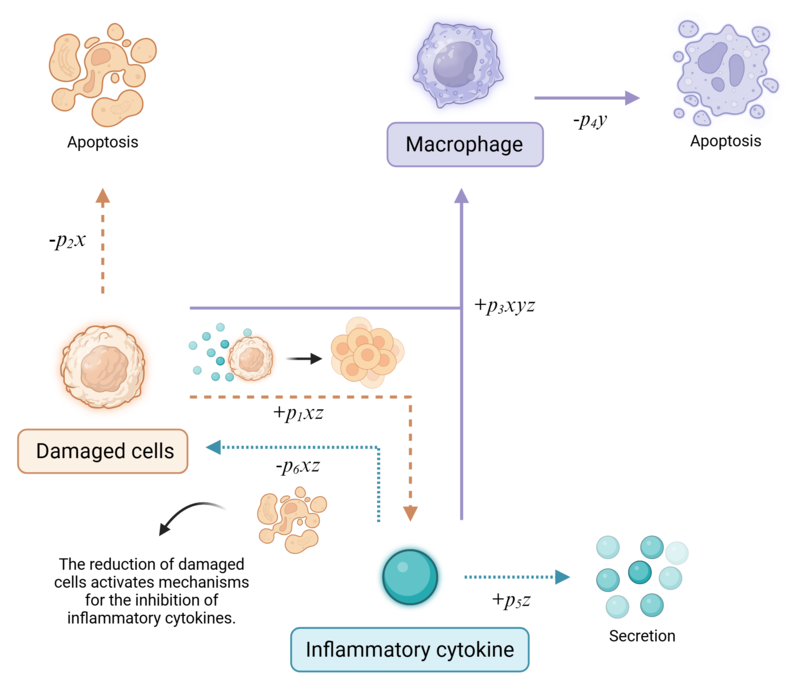

*Figure 1. Predator-prey system model of the inflammation process. [Made in BioRender].*

## Simulation data

    to     xo       yo       zo  
    __    _____    _____    _____

     0    6.423     1.72    6.319
     7    6.752    2.224    6.228
    14    7.414    2.873    6.043
    21    7.852    3.467    5.832
    28     8.15    4.126    5.682
    35    8.548    4.815    5.456
    42    8.997    5.615     5.13
    49     8.94    6.476    4.892
    56    8.581    7.091    4.615
    63    8.099    7.457    4.188
    70    7.661    7.715    3.911



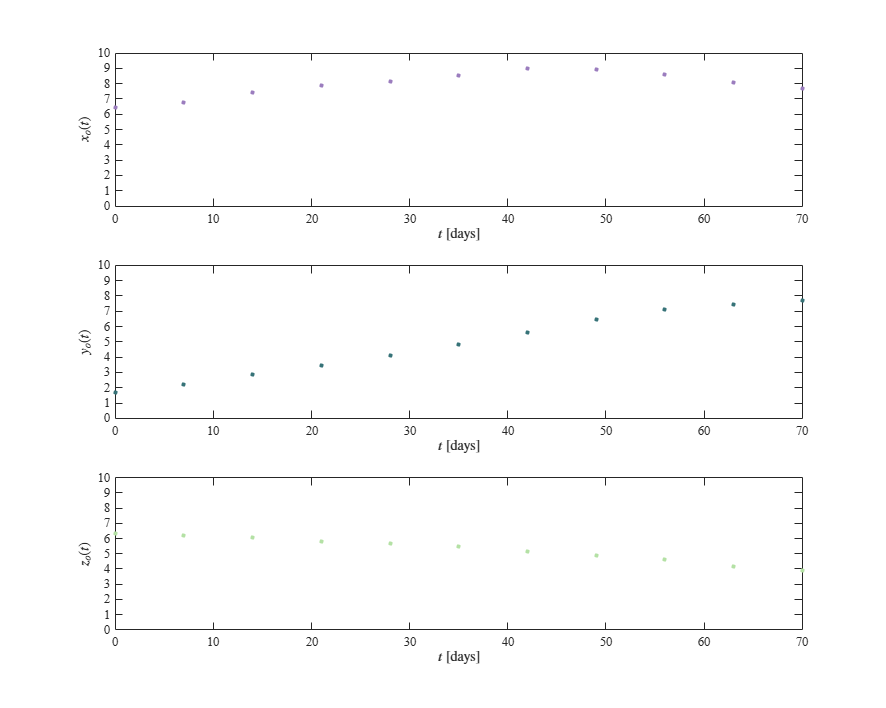

clc; clear; close all; warning('off','all')
sys = readmatrix('data.csv');
to = sys(:,1);
xo = sys(:,2);
yo = sys(:,3);
zo = sys(:,4);
T = array2table([to,xo,yo,zo],'VariableNames',{'to','xo','yo','zo'});
disp(T); plotdata(to,xo,yo,zo); exportgraphics(gcf, 'Experimental Data.pdf', 'ContentType', 'vector');

## Smooth data

xo = smoothdata(xo);
yo = smoothdata(yo);
zo = smoothdata(zo);
T = array2table([to,xo,yo,zo],'VariableNames',{'to','xo','yo','zo'});
writetable(T, 'smooth_data.csv');
disp(T); plotdata(to,xo,yo,zo); exportgraphics(gcf, 'Smooth Data.pdf', 'ContentType', 'vector');

## Fit data

rho1 = 0.00705; rho2 = 0.0351;
rho3 = 0.00198; rho4 = 0.0667;
rho5 = 0.0187; rho6 = 0.00306;
P = [rho1, rho2, rho3, rho4, rho5, rho6];
[mdl, xa, ya, za] = variant(to,xo,yo,zo,P); plotResults(to, [xo,xa], [yo,ya], [zo,za]); exportgraphics(gcf, 'System Regression.pdf', 'ContentType', 'vector');

## Equilibrium points and Jacobian matrix

syms x y z rho1 rho2 rho3 rho4 rho5 rho6
dx = rho1*x*z - rho2*x;
dy = rho3*x*y*z - rho4*y
dz = rho5*z - rho6*x*z;
J = jacobian([dx,dy,dz],[x,y,z]);
fprintf('Jacobian matrix:'); disp(J);
dx = rho1*x*z - rho2*x == 0;
dy = rho3*x*y*z - rho4*y == 0;
dz = rho5*z - rho6*x*z == 0;
edos = solve([dx,dy,dz],[x,y,z]);
fprintf(['The system has ', num2str(length(edos.x)), ' equilibrium points.']);
X0 = edos.x(1); Y0 = edos.y(1); Z0 = edos.z(1);
X1 = edos.x(2); Y1 = edos.y(2); Z1 = edos.z(2);
syms x0 y0 z0 x1 y1 z1
fprintf('Equilibrium points of the system:\n'); disp([x0, y0, z0, X0, Y0, Z0]); disp([x1, y1, z1, X1, Y1, Z1]);
clear rho1 rho2 rho5 rho6
rho1 = 0.00705; rho2 = 0.0351;
rho5 = 0.0187; rho6 = 0.00306;
disp('(x0, y0, z0) = (0, 0, 0)'); disp(['(x1,y1,z1) = (', num2str(rho5/rho6), ', ', num2str(0), ', ', num2str(rho2/rho1), ')']);

## Local stability

clear rho1 rho2 rho3 rho4 rho5 rho6
rho1 = 0.00705; rho2 = 0.0351;
rho3 = 0.00198; rho4 = 0.0667;
rho5 = 0.0187; rho6 = 0.00306;
dx = rho1*x*z - rho2*x == 0;
dy = rho3*x*y*z - rho4*y == 0;
dz = rho5*z - rho6*x*z == 0;
edos = solve([dx,dy,dz],[x,y,z]);
x0 = edos.x(1); y0 = edos.y(1); z0 = edos.z(1);
x1 = edos.x(2); y1 = edos.y(2); z1 = edos.z(2);

clear x y z
x = double([x0; x1]);
y = double([y0; y1]);
z = double([z0; z1]);
var = {'(x0, y0, z0)';'(x1, y1, z1)'};
Equilibria = table(x,y,z,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye','ze'};
fprintf('Equilibrium points of the system:\n'); disp(Equilibria);
L = zeros(length(x),3);
for i = 1:length(x)
     J = [rho1*z(i) - rho2, 0, rho1*x(i);
         0, rho3*z(i) - rho4, rho3*y(i);
         - rho6*z(i), 0, rho5 - rho6*x(i)]
     L(i,:) = eig(J);
end
L1 = L(:,1); L2 = L(:,2); L3 = L(:,3);
Lambdas = table(L1,L2,L3,'RowNames',var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas);

## Positivity analysis

syms x y z rho1 rho2 rho3 rho4 rho5 rho6

dx = rho1*x*z - rho2*x;
dy = rho3*x*y*z - rho4*y;
dz = rho5*z - rho6*x*z;

dx0 = subs(dx, {x, z}, {0, 0});
dy0 = subs(dy, {x, y, z}, {0, 0, 0});
dz0 = subs(dz, {x, z}, {0, 0});

fprintf('dx en (0,0,0): %s\n', string(dx0)); fprintf('dy en (0,0,0): %s\n', string(dy0)); fprintf('dz en (0,0,0): %s\n', string(dz0));

## 2t prediction

rho1 = 0.00705; rho2 = 0.0351;
rho3 = 0.00198; rho4 = 0.0667;
rho5 = 0.0187; rho6 = 0.00306;
P = [rho1, rho2, rho3, rho4, rho5, rho6];
tend = 140;
[ta, xa, ya, za] = predict(xo, yo, zo, tend, P); plotPrediction(to,xo,yo,zo,ta,xa,ya,za,140); exportgraphics(gcf, '2t Prediction.pdf', 'ContentType', 'vector');

## t = 100 prediction

rho1 = 0.00705; rho2 = 0.0351;
rho3 = 0.00198; rho4 = 0.0667;
rho5 = 0.0187; rho6 = 0.00306;
P = [rho1, rho2, rho3, rho4, rho5, rho6];
tend = 1000;
[ta, xa, ya, za] = predict(xo, yo, zo, tend, P); plotPrediction(to,xo,yo,zo,ta,xa,ya,za,1000); exportgraphics(gcf, '1000 Prediction.pdf', 'ContentType', 'vector');

## Functions

### Plot data

function plotdata(t, x, y, z)
    set(figure(), 'Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [1,1,25,20])
    
    colores = [155, 125, 190;
               55, 115, 120;
               180, 225, 165;
               230, 185, 235] / 255;

    % Subplot 1 - x
    subplot(3,1,1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(t, x, '.', 'MarkerSize', 10, 'LineWidth', 1, 'Color', colores(1,:));
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$x_o(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);

    % Subplot 2 - y
    subplot(3,1,2);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(t, y, '.', 'MarkerSize', 10, 'LineWidth', 1, 'Color', colores(2,:));
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$y_o(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);

    % Subplot 3 - z
    subplot(3,1,3);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(t, z, '.', 'MarkerSize', 10, 'LineWidth', 1, 'Color', colores(3,:));
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$z_o(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);
end

### System regression

function [mdl, xa, ya, za] = variant(to, xo, yo ,zo, P)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    to = [to; to; to];
    fo = [xo; yo; zo];

    function fi = model(p, t)
        rho1 = p(1); rho2 = p(2);
        rho3 = p(3); rho4 = p(4); rho5 = p(5);
        rho6 = p(6);
        dt = 1E-2;
        t = reshape(t, [], 3); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        z = zeros(length(time),1); z(1) = z0;

        for i = 1:n
            [fx, fy, fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn, fyn, fzn] = f(xn, yn, zn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        function [dx,dy,dz] = f(x,y,z)
            dx = rho1*x*z - rho2*x;
            dy = rho3*x*y*z - rho4*y;
            dz = rho5*z - rho6*x*z;
        end

        xi = zeros(length(t),1);  
        yi = zeros(length(t),1);
        zi = zeros(length(t),1);
        
        for i = 1:length(t)
            k = abs(time - t(i)) < 1E-9; 
            xi(i) = x(k);
            yi(i) = y(k);
            zi(i) = z(k);
        end

        fi = [xi;yi;zi];
    end

    mdl = fitnlm(to,fo,@model,P); 
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE; 
    tval = tinv(1 - alpha/2,dof);
    MoE = SE*tval;

    Parameters = ['rho1';'rho2';'rho3';'rho4';'rho5';'rho6'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    
    disp(Results)

    fa = mdl.Fitted;
    fn = reshape(fa,[],3);
    xa = fn(:,1);
    ya = fn(:,2);
    za = fn(:,3);
end

### System prediction

function [time, xa, ya, za] = predict(xo, yo ,zo, tend, P)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    rho1 = P(1); rho2 = P(2);
    rho3 = P(3); rho4 = P(4);
    rho5 = P(5); rho6 = P(6);
    dt = 1E-2;
    time = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros(length(time),1); x(1) = x0;
    y = zeros(length(time),1); y(1) = y0;
    z = zeros(length(time),1); z(1) = z0;

    for i = 1:n
        [fx, fy, fz] = f(x(i),y(i),z(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        zn = z(i) + fz*dt;
        [fxn, fyn, fzn] = f(xn, yn, zn);
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
        z(i+1) = z(i) + (fz + fzn)*dt/2;
    end

    xa = x;
    ya = y;
    za = z;

    function [dx,dy,dz] = f(x,y,z)
        dx = rho1*x*z - rho2*x;
        dy = rho3*x*y*z - rho4*y;
        dz = rho5*z - rho6*x*z;
    end
end

### Plot results

function plotResults(to, xo, yo, zo)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,25,20]);

    colores = [155, 125, 190;
               55, 115, 120;
               180, 225, 165;
               230, 185, 235]/255;

    % Subplot 1 - x
    subplot(3,1,1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    h1 = plot(to, xo(:,2), '-', 'LineWidth', 1, 'Color', colores(1,:));
    h2 = plot(to, xo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);
    legend([h2, h1], {'$x_o(t)$', '$x_a(t)$'}, 'Interpreter', 'latex', 'Location', 'northeastoutside');

    % Subplot 2 - y
    subplot(3,1,2);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    h3 = plot(to, yo(:,2), '-', 'LineWidth', 1, 'Color', colores(2,:));
    h4 = plot(to, yo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);
    legend([h4, h3], {'$y_o(t)$', '$y_a(t)$'}, 'Interpreter', 'latex', 'Location', 'northeastoutside');

    % Subplot 3 - z
    subplot(3,1,3);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    h5 = plot(to, zo(:,2), '-', 'LineWidth', 1, 'Color', colores(3,:));
    h6 = plot(to, zo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$z(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);
    legend([h6, h5], {'$z_o(t)$', '$z_a(t)$'}, 'Interpreter', 'latex', 'Location', 'northeastoutside');
end

### Plot prediction

function plotPrediction(to, xo, yo, zo, ta, xa, ya, za, typeplot)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,25,20]);

    colores = [155, 125, 190;
               55, 115, 120;
               180, 225, 165;
               230, 185, 235]/255;

    switch typeplot
        case 140
            x_lim = [0 140];
            x_ticks = 0:20:140;
            y_lims = {[0 10], [0 20], [0 10]};
            y_ticks = {0:1:10, 0:2:20, 0:1:10};
        case 1000
            x_lim = [0 1000];
            x_ticks = 0:100:1000;
            y_lims = {[0 10], [0 20], [0 10]};
            y_ticks = {0:1:10, 0:2:20, 0:1:10};
    end

    % Subplot 1 - x
    subplot(3,1,1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    h1 = plot(ta, xa, '-', 'LineWidth', 1, 'Color', colores(1,:));
    h2 = plot(to, xo, 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    xlim(x_lim); xticks(x_ticks);
    ylim(y_lims{1}); yticks(y_ticks{1});
    legend([h2, h1], {'$x_o(t)$', '$x_a(t)$'}, 'Interpreter', 'latex', 'Location', 'northeastoutside');

    % Subplot 2 - y
    subplot(3,1,2);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    h3 = plot(ta, ya, '-', 'LineWidth', 1, 'Color', colores(2,:));
    h4 = plot(to, yo, 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim(x_lim); xticks(x_ticks);
    ylim(y_lims{2}); yticks(y_ticks{2});
    legend([h4, h3], {'$y_o(t)$', '$y_a(t)$'}, 'Interpreter', 'latex', 'Location', 'northeastoutside');

    % Subplot 3 - z
    subplot(3,1,3);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    h5 = plot(ta, za, '-', 'LineWidth', 1, 'Color', colores(3,:));
    h6 = plot(to, zo, 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$ [days]', 'Interpreter', 'latex');
    ylabel('$z(t)$', 'Interpreter', 'latex');
    xlim(x_lim); xticks(x_ticks);
    ylim(y_lims{3}); yticks(y_ticks{3});
    legend([h6, h5], {'$z_o(t)$', '$z_a(t)$'}, 'Interpreter', 'latex', 'Location', 'northeastoutside');
end